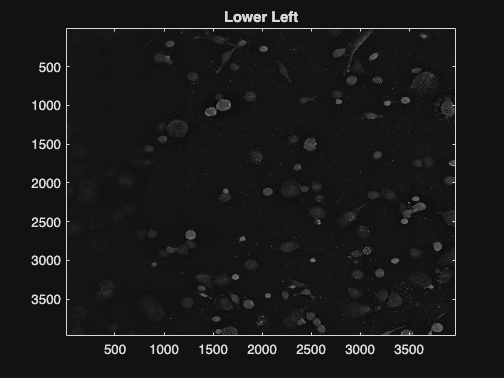

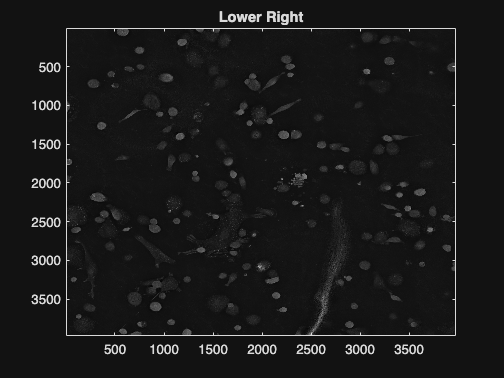

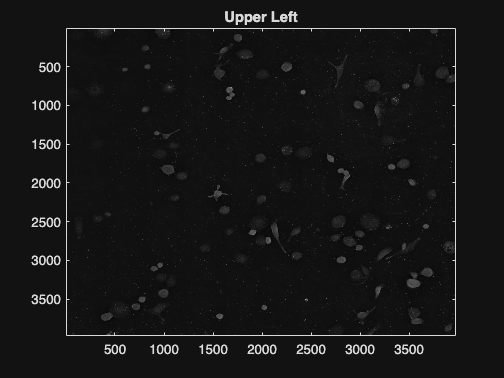

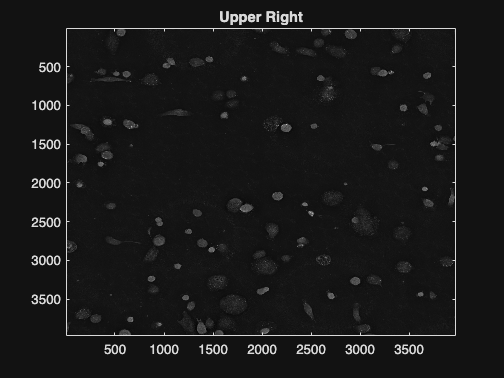

% INPUT

filenames = {"Evaluation/ctrl_ll.tiff", "Evaluation/ctrl_lr.tiff", "Evaluation/ctrl_ul.tiff", "Evaluation/ctrl_ur.tiff"};
images = cell(1, length(filenames));
titles = {"Lower Left", "Lower Right", "Upper Left", "Upper Right"};

for i = 1:length(filenames)
    tiff_obj = Tiff(filenames{i}, "r");
    images{i} = read(tiff_obj);
    close(tiff_obj);
end

for i = 1:length(images)
    figure;
    imagesc(images{i});
    colormap(gray(256));
    title(titles{i});
end

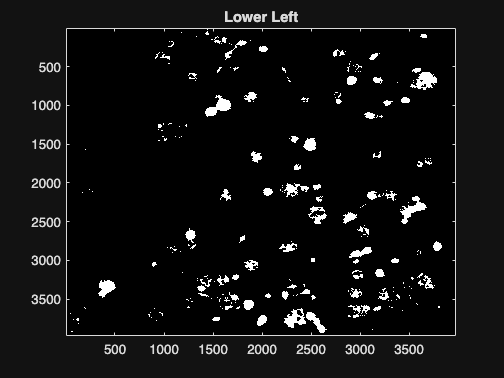

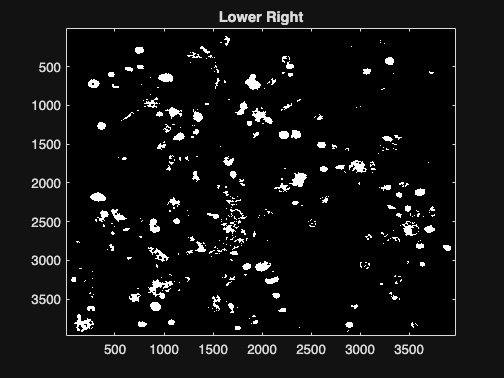

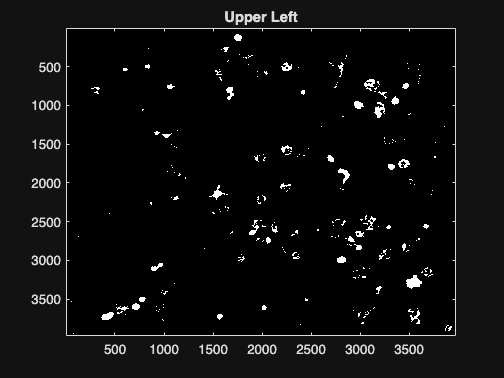

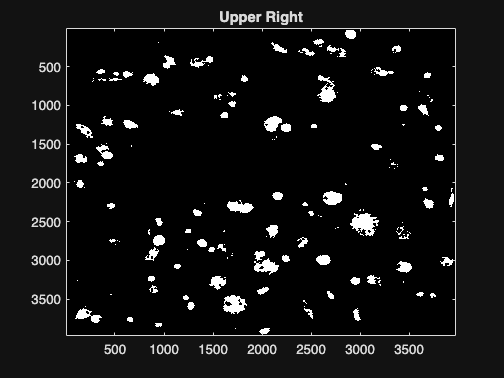

% PROCESSING

processed_images = cell(1, length(filenames));

for i = 1:length(images)
    
    [~, threshold] = edge(images{i}, 'sobel');
    fudge = 1;
    processed_images{i} = edge(images{i}, 'sobel', threshold * fudge);

    se90 = strel("line", 3, 90);
    se0 = strel("line", 3, 0);
    processed_images{i} = imdilate(processed_images{i}, [se90 se0]);

    img_fill = imfill(processed_images{i}, "holes");
    sc = strel("disk", 5);
    out_img = imclose(img_fill, sc);
    processed_images{i} = imclose(out_img, sc);

    processed_images{i} = imclearborder(processed_images{i}, 8);

    seD = strel("diamond", 4);
    img_final = imerode(processed_images{i}, seD);
    processed_images{i} = imerode(img_final, seD);
end

for i = 1:length(images)
    figure;
    imagesc(processed_images{i});
    colormap(gray(256));
    title(titles{i});
end

% OBJECT COUNT

num_objects_before = cell(1, length(filenames));
num_after = cell(1, length(filenames));
labeled_images = cell(1, length(filenames));

for i = 1:length(processed_images)
    img_label = bwlabel(processed_images{i});
    labeled_images{i} = img_label;
    num_objects_before{i} = max(max(img_label));
end

for i = 1:length(processed_images)
    img_label = bwlabel(processed_images{i});
    bw = imbinarize(img_label);
    cc = bwconncomp(bw);
    stats = regionprops("table", cc, "Area");
    selection = (stats.Area > 500 & stats.Area < 5000);
    filtered = cc2bw(cc, ObjectsToKeep=selection);
    filtered_bw = bwlabel(filtered);
    num_after{i} = max(max(filtered_bw));
end

num_objects_before

num_objects_before = 1×4 cell array
    {[366]}    {[493]}    {[375]}    {[246]}


sum([num_objects_before{:}])

ans = 1480

num_after

num_after = 1×4 cell array
    {[58]}    {[114]}    {[68]}    {[37]}


sum([num_after{:}])

ans = 277

% CLEAR DIRECTORY

% Create folder if it doesn't exist
output_folder = 'cache';
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
else
    % Clear all files in the folder
    if exist("cache/pic", 'dir')
        delete(fullfile('cache/pic', '*'));
        rmdir("cache/pic");
    end
    
    if exist("cache/objects", 'dir')
        rmdir("cache/objects", 's');
    end
    delete(fullfile(output_folder, '*'));
end

% Create png copy of the image
mkdir("cache/pic");
for i = 1:length(filenames)
    png = uint8(255 * mat2gray(images{i}));
    png_name = sprintf('cache/pic/%s.png', titles{i});
    imwrite(png, png_name);
end

% EXTRACT OBJECT

num_objects_after = 0;
min_area = 500;
max_area = 5000;
mkdir("cache/objects");

for i = 1:length(labeled_images)
    for k = 1:num_objects_before{i}
        % Create a binary image for the current object
        img_object = (labeled_images{i} == k);
        % Calculate the area of the current object
        object_area = regionprops(img_object, 'Area');
        object_area = object_area.Area;
        
        % Check if the object area is within the specified range
        if object_area >= min_area && object_area <= max_area
            % Calculate the centroid of the object
            stats = regionprops(img_object, 'Centroid');
            centroid = stats.Centroid;

            % Define the bounding box around the centroid
            half_size = 75; % Half the size of the desired output (150x150)
            min_row = max(1, round(centroid(2) - half_size));
            max_row = min(size(images{i}, 1), round(centroid(2) + half_size));
            min_col = max(1, round(centroid(1) - half_size));
            max_col = min(size(images{i}, 2), round(centroid(1) + half_size));

            % Adjust the bounding box to ensure it is 150x150
            if (max_row - min_row + 1) < 150
                if min_row == 1
                    max_row = min_row + 149;
                else
                   min_row = max_row - 149;
                end
            end
            if (max_col - min_col + 1) < 150
                if min_col == 1
                    max_col = min_col + 149;
                else
                    min_col = max_col - 149;
                end
            end

            % Extract the 150x150 region around the centroid
            target = images{i}(min_row:max_row, min_col:max_col);
            
            % If the extracted region is not 150x150, pad it with black pixels
            if size(target, 1) < 150 || size(target, 2) < 150
                padded_target = zeros(150, 150, 'uint8');
                row_offset = floor((150 - size(target, 1)) / 2) + 1;
                col_offset = floor((150 - size(target, 2)) / 2) + 1;
                padded_target(row_offset:row_offset+size(target, 1)-1, col_offset:col_offset+size(target, 2)-1) = target;
                target = padded_target;
            end

            % Clean border and convert to uint8
            target_clear = imclearborder(target, 8);
            output = imclearborder(target_clear, 8);
            output = uint8(255 * mat2gray(output));
            output = repmat(output, [1 1 3]);

            % Save each object as png image
            output_filename = sprintf('cache/objects/object_%d.png', num_objects_after + 1);
            imwrite(output, output_filename);

            % Increment the count of objects after filtering
            num_objects_after = num_objects_after + 1;
        end
    end
end

% CLASSIFICATION

network = coder.loadDeepLearningNetwork('RESNET18.mat');
model = dag2dlnetwork(network);

class = ["M0" "M1" "M2a" "M2c"];
class = categorical(class);
imds = imageDatastore("cache/objects");
imdsAug = augmentedImageDatastore([224 224 3], imds);

scores = minibatchpredict(model, imdsAug);
predictedClass = scores2label(scores, class);

num_M0 = sum(predictedClass(:) == 'M0');
num_M1 = sum(predictedClass(:) == 'M1');
num_M2a = sum(predictedClass(:) == 'M2a');
num_M2c = sum(predictedClass(:) == 'M2c');

result = [num_M0 num_M1 num_M2a num_M2c]

result =     77   114    36    51


% PLOT RESULT

figure
piechart(result, class)
title("Control")